clear all
close all
%addpath("altmany-export_fig-3.43.0.0/")

% set parameters
global SampleNum
global x1
global x2
global y1
global y3

%set xy size and z-stack size
xysz= 1608;
zsz= 101;

mkdir('Ncoords_1')

mkdir('Ncoords_1/parsed')

% mkdir('raw_images_1')
% mkdir('tiffs')

save_tiffs = 1;
save_age = 1;

SampleNum = '6';

% find and segment nuclei
FileName = ['sequential_405_denoised/405_0_' SampleNum '.mat'];

load(FileName)


## select all embryos you want to segment - re-run this code until all embryos in the image are saved 

mkdir cropped\


FOV = 2 %which embryo are we analyzing now (if > 1 in the sample)

FOV = 2

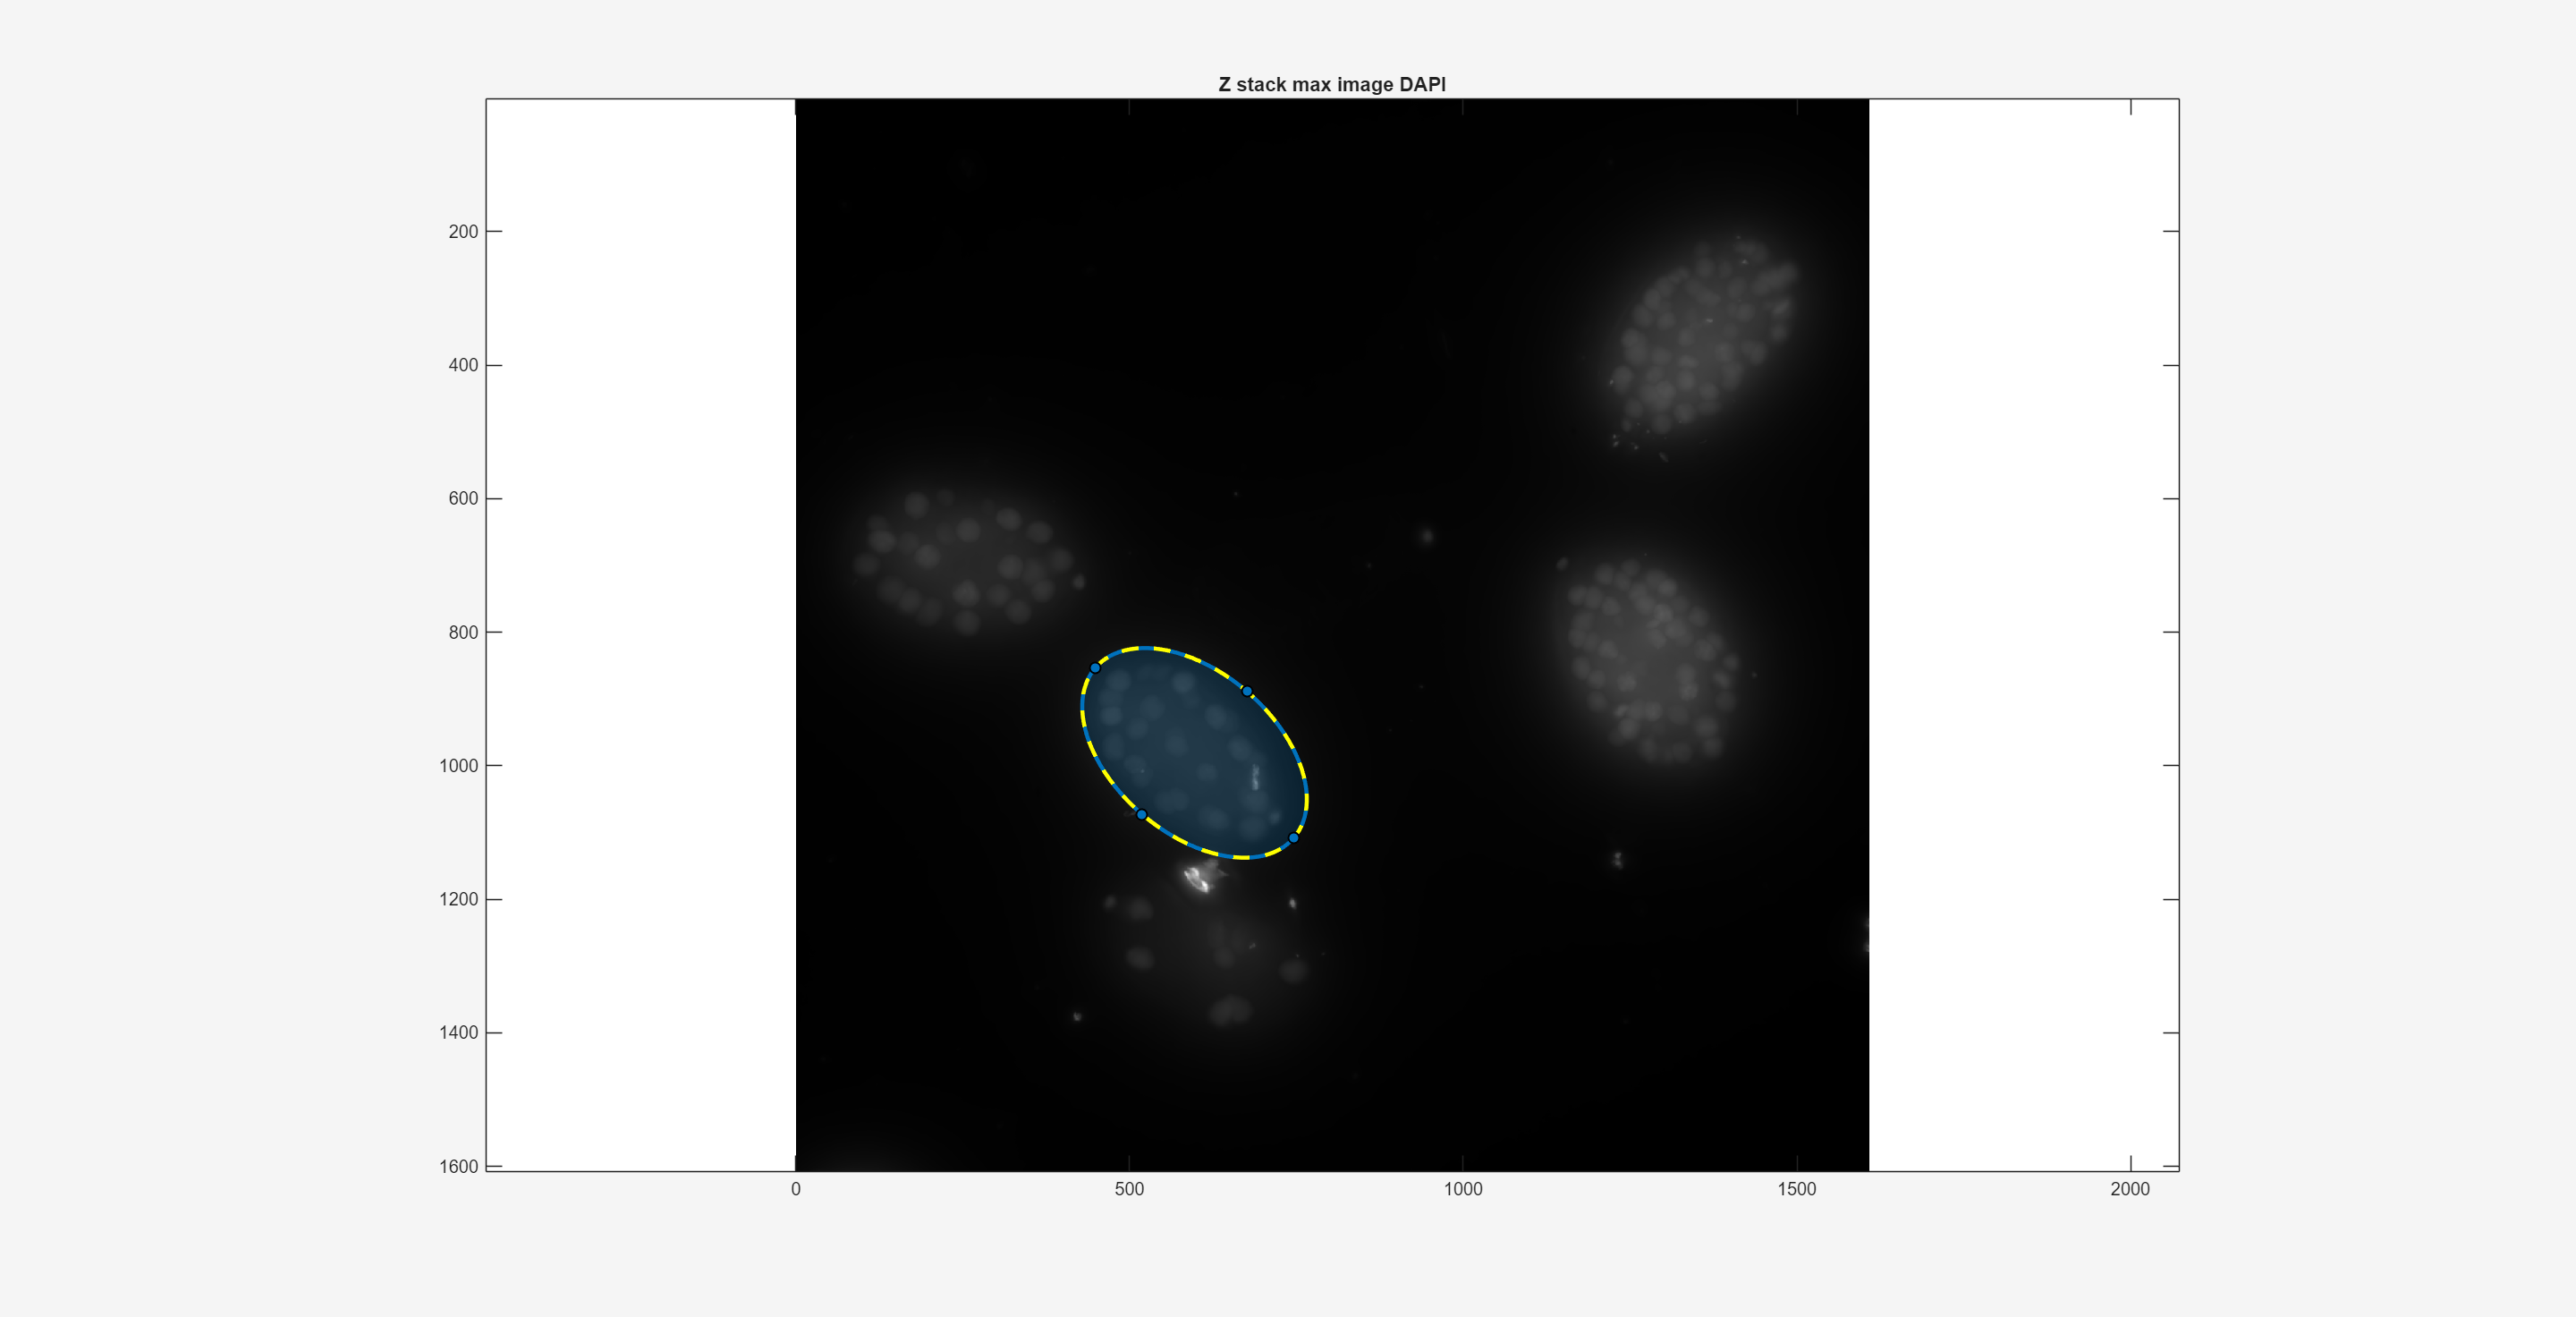


ImDAPI = max(ImageStack405,[],3);
figure

imagesc(ImDAPI)
colormap gray
axis equal
title('Z stack max image DAPI')%flattened image of nuclei full xyz stack

embryo = drawellipse('StripeColor','y');

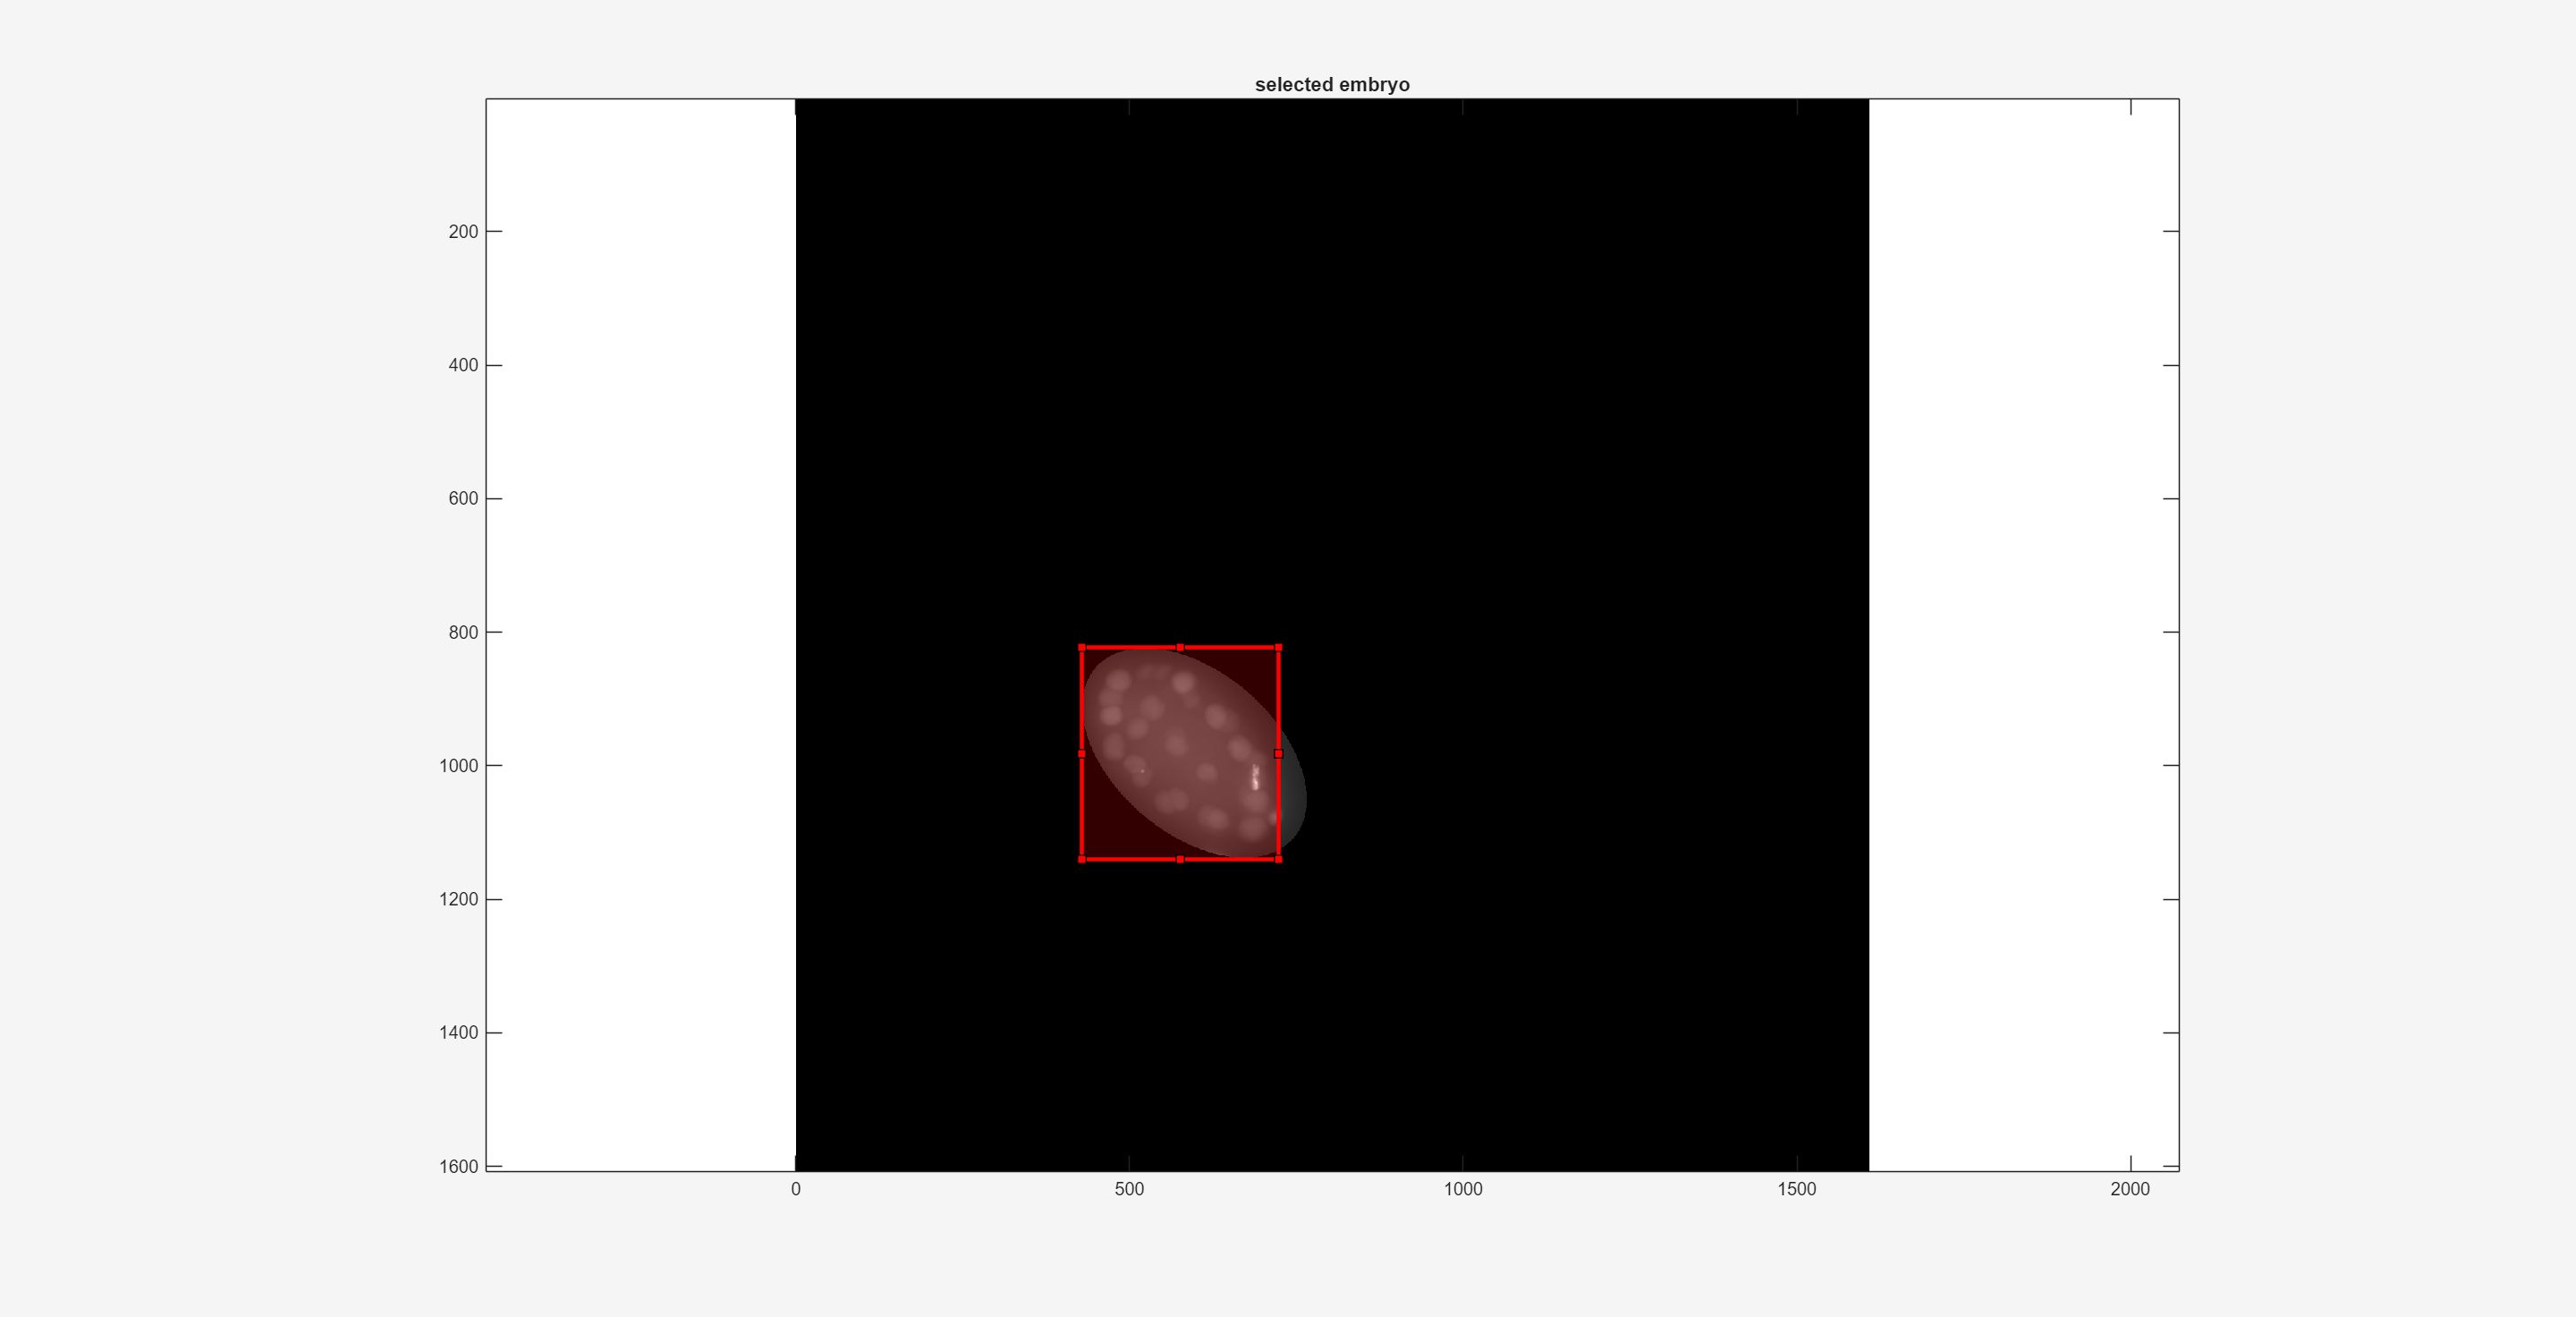

roirect =   Rectangle with properties:

         Position: [428.6300 822.5900 294.8000 317.5800]
    RotationAngle: 0
      AspectRatio: 1.0773
            Label: ''
            Color: [1 0 0]
           Parent: [1×1 Axes]
          Visible: on
         Selected: 0

  Show all properties




BW = createMask(embryo);
Embryo = zeros(xysz,xysz,zsz);
for i = 1:zsz
test = ImageStack405(:,:,i);
test(BW == 0) = 0;
Embryo(:,:,i) = test;
end

figure
set(gcf,'Visible','on')
imagesc(max(Embryo,[],3))
colormap gray
axis equal
title('selected embryo')

roirect=drawrectangle('Color', 'r')

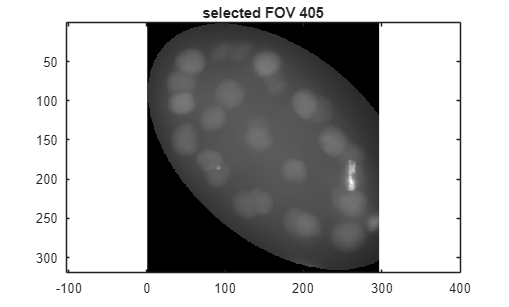

x1 = ceil(roirect.Position(1,1));
x2 = ceil(roirect.Position(1,1))+ceil(roirect.Position(1,3));
y1 = ceil(roirect.Position(1,2));
y3 = ceil(roirect.Position(1,2))+ceil(roirect.Position(1,4));

% coords_file = strcat('Ncoords_1/parsed/405_0_', num2str(SampleNum), '_FOV', num2str(FOV), '_xy_coords.mat'
% ^ turn this on and replace string inside save() below if there is an
% issue saving

save(['Ncoords_1/parsed/Sample' num2str(SampleNum) 'FOV' num2str(FOV) 'coords.mat'],'x1', 'x2', 'y1', 'y3')

I = Embryo(y1:y3, x1:x2, :);
figure
ImDAPI = max(I,[],3);
imagesc(ImDAPI)
colormap gray
axis equal
%caxis([0 3500])
title('selected FOV 405')

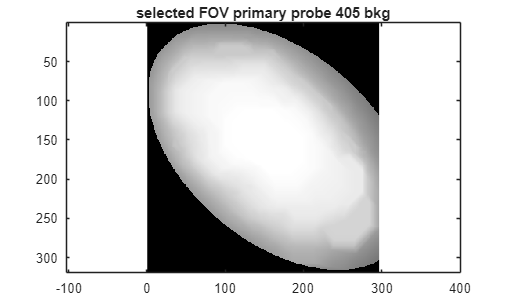


%correct for uneven background illumination

se = strel('disk',30); 
background = imopen(I,se);
figure
imagesc(max(background,[],3))
colormap gray
axis equal
%caxis([0 3500])
title('selected FOV primary probe 405 bkg')

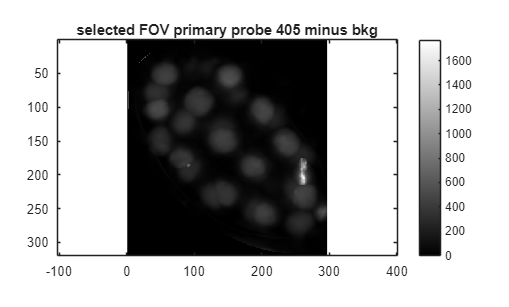

% 
I2 = I - background;
ImDAPI = max(I2,[],3);
figure
%set(gcf,'Visible','on')
imagesc(max(I2,[],3))
colormap gray
axis equal
colorbar
%caxis([0 2000])
title('selected FOV primary probe 405 minus bkg')

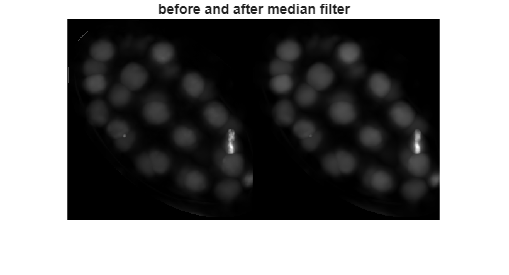


J = medfilt3(I2, [5 5 5]);
figure
imshowpair(max(I2,[],3),max(J,[],3),'montage')
title('before and after median filter')


I3 = uint16(J);

save( ['cropped/405_0_' num2str(SampleNum) '_FOV' num2str(FOV) '.mat'],'I3');

% clear; 

% if you have more images in your imaging set, go back to the first code
% section and continue to process (ellipse & crop) the images 

%convert images to .tiff format for segmentation in cellpose

mkdir('sampleTiffs') %this stores intermediate sample tiffs

imgDir = 'cropped/';
to_segment = dir(fullfile(imgDir, '*.mat'));

for k = 1:length(to_segment)
  baseFileName = to_segment(k).name;
  fullFileName = fullfile(imgDir, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  names = split(baseFileName,".");
  samplename = names(1,:);
  Image = load(fullFileName,"I3");
 
  save_filename = strcat('sampleTiffs/', samplename, '.tif');
  save_filename = string(save_filename);


  normed = uint16(Image.I3); % normalize image or MATLAB will get confused re what values to save
  imwrite(normed(:,:,1), save_filename);
  for i = 2:size(normed,3)
   imwrite(normed(:,:,i), save_filename, 'WriteMode','append');
  end
end

Now reading cropped\405_0_1_FOV1.mat
Now reading cropped\405_0_1_FOV2.mat
Now reading cropped\405_0_1_FOV3.mat
Now reading cropped\405_0_2_FOV1.mat
Now reading cropped\405_0_2_FOV2.mat
Now reading cropped\405_0_2_FOV3.mat
Now reading cropped\405_0_3_FOV1.mat
Now reading cropped\405_0_3_FOV2.mat
Now reading cropped\405_0_4_FOV1.mat
Now reading cropped\405_0_4_FOV2.mat
Now reading cropped\405_0_4_FOV3.mat
Now reading cropped\405_0_6_FOV1.mat
Now reading cropped\405_0_6_FOV2.mat



fprintf('All images saved as .tiffs!')

All images saved as .tiffs!

%STOP! now it's time to move to the cluster to segment nuclei in Cellpose
% use the script batch_segment.sh to segment the images and then come back with the
% .tiff files!

% to run on the cluster: 
% log in
% in the command line type in 'sbatch batch_segment.sh'
% make sure that your input and output folders are correct before
% submitting the job


%feed images back into pipeline

cropDir = 'cropped/';
cropfiles = dir(fullfile(cropDir, '*.mat'));

for k = 1:length(cropfiles)
    baseFileName = cropfiles(k).name;
    fullLoc = fullfile(cropDir, baseFileName);


    %here read in as an array of images
    realImg = load(fullLoc,"I3");
    fovs{k} = realImg.I3;

end
clear maskDir maskFileName fullLoc

%into pipeline

maskDir = 'masks/';
maskfiles = dir(fullfile(maskDir, '*.tif'));
mkdir matMasks


for k = 1:length(maskfiles)
    baseFileName = maskfiles(k).name;
    names = split(baseFileName,".");
    samplename = names(1,:);
    samplename = string(samplename);
    fullLoc = fullfile(maskDir, baseFileName);


    %here read in as an array of images
    imgMask = tiffreadVolume(fullLoc);
    filename = strcat('matMasks/', samplename, '.mat'); 
    save(filename, 'imgMask');
    imgs{k} = imgMask;

end
clear maskDir maskFileName

## calculate nstats

%get stats/stage the embryos: this will run for ALL embryos in your dataset

sampleNum = 6

sampleNum = 6

FOV = 2

FOV = 2


FileName = strcat('matMasks/405_0_', num2str(sampleNum), '_FOV', num2str(FOV),'_cp_masks.mat')

FileName = 'matMasks/405_0_6_FOV2_cp_masks.mat'

matchFile = strcat('cropped/405_0_', num2str(sampleNum), '_FOV', num2str(FOV), '.mat');

L = load(FileName);
L = L.imgMask;

L = imdilate(L,true(8));
nucL = L;
clear L


% save all this separately per embryo
nstats = regionprops3(nucL, 'all');

Lmax = max(nucL,[],3);
nucLrgb = label2rgb(Lmax,'jet','w','shuffle');
% figure
% imshow(nucLrgb)
% title('colored watershed label matrix nuclei')

age = height(nstats);
ncenters = nstats.Centroid;
nvols = nstats.Volume;
min(nvols(:))

ans = 10152

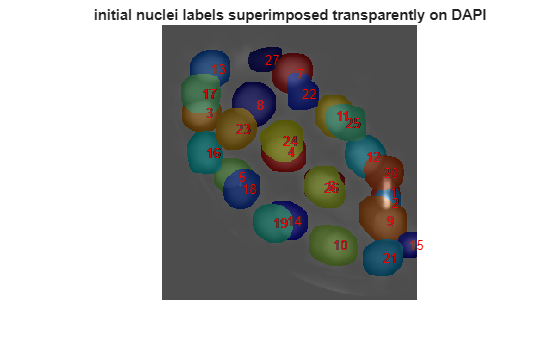


[a b]= size(ncenters);
nucnums = zeros(a,1);
nucID = find(nucnums >=0);
clear a b nucnums

Lmax = max(nucL,[],3);
nucLrgb = label2rgb(Lmax,'jet','w','shuffle');


% Force k to the correct image for (sampleNum, FOV)
key = sprintf('405_0_%d_FOV%d', sampleNum, FOV);    
if ~exist('cropfiles','var') || ~isstruct(cropfiles) || ~isfield(cropfiles,'name')
    cropDir = 'cropped/';
    cropfiles = dir(fullfile(cropDir, '*.mat'));
end
assert(~isempty(cropfiles), 'No .mat files found in %s', cropDir);
names = {cropfiles.name};
names_noext = regexprep(lower(names), '\.mat$', '');
k = find(strcmpi(names_noext, lower(key)), 1, 'first');
assert(~isempty(k), 'Could not find %s.mat in cropped/', key);


figure
imagesc(max(fovs{k},[],3));
colormap gray
hold on
himage = imshow(nucLrgb);
himage.AlphaData = 0.3;
text(nstats.Centroid(:,1), nstats.Centroid(:,2), nstats.Centroid(:,3)-5, num2str((1:height(nstats))'), 'Color','red')
title(['initial nuclei labels superimposed transparently on DAPI' ])

## specify and remove bad nucs

badnucIDs = [1 2 15];
nucL_v2=nucL;
if length(badnucIDs)>0
    for i = 1:length(badnucIDs)
        nucL_v2(find(nucL_v2 == badnucIDs(1,i))) = 0;
    end
end

nstats = regionprops3(nucL_v2, 'all');
%nstats(any(isnan(nstats.Centroid),2), :) = []; %i added this for 20250930
%sample 6 FOV2 where i deleted badnucs 1, 2, and 15
for i =1:height(nstats)-length(badnucIDs)
    if nstats.Volume(i) ==0
        nstats(i,:)=[];
    end
end

%2D visualization via MIP
Lmax = max(nucL_v2,[],3);
nucLrgb = label2rgb(Lmax,'jet','w','shuffle');
% figure
% imshow(nucLrgb)
% title('colored watershed label matrix nuclei')

%recompute quantities after relabeling
age = height(nstats)

age = 24

ncenters = nstats.Centroid;
nvols = nstats.Volume;
min(nvols(:))

ans = 10758

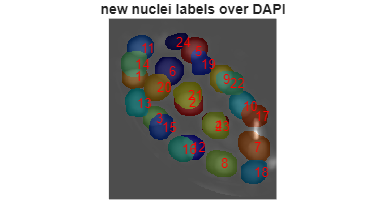


[a b]= size(ncenters);
nucnums = zeros(a,1);
nucID = find(nucnums >=0);
clear a b nucnums

ImDAPI = max(fovs{k}, [], 3);
figure
imagesc(ImDAPI); colormap gray; axis image off; hold on
himage = imshow(nucLrgb); himage.AlphaData = 0.3;
labels = string(nucID(:));
text(ncenters(:,1), ncenters(:,2), labels, 'Color','red')
title('new nuclei labels over DAPI')


clear nucL
nucL=nucL_v2;

% map each row in nstats to its actual label in nucL_v2
numNuclei = height(nstats);
nucLabels = zeros(numNuclei,1);
for i = 1:numNuclei
    cx = round(ncenters(i,1));
    cy = round(ncenters(i,2));
    cz = round(ncenters(i,3));
    nucLabels(i) = nucL_v2(cy, cx, cz);  % (row, col, z)
end

## Find the P-cell nucleus 

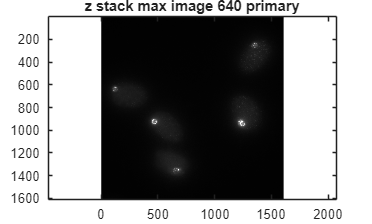

%% Parameters
Thresh640 = 1000; 
dilateThresh = 5; 
erodeThresh = 5; 
TerrbinaryThresh = 4; 

%% Load 640 channel
FileName = sprintf('sequential/640_0_%d.mat', sampleNum); 
load(FileName)        

Im = max(ImageStack640,[],3);
figure
imagesc(Im)
colormap gray
axis equal
title('z stack max image 640 primary')
caxis([100 5000])

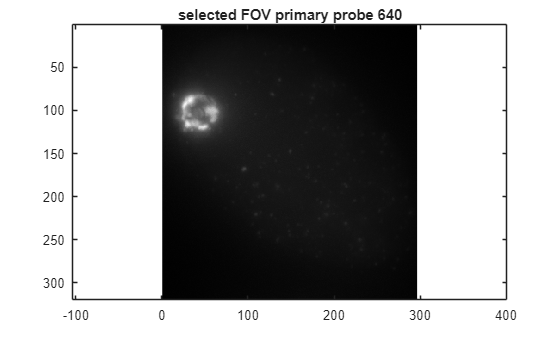


load(['Ncoords_1/parsed/Sample' num2str(sampleNum) 'FOV' num2str(FOV) 'coords.mat'], ...
     'x1', 'x2', 'y1', 'y3');

%set xy size and z-stack size
xysz= 1608;
zsz= 101;

BW = false(xysz, xysz);
BW(y1:y3, x1:x2) = true;
GEmbryo = zeros(xysz,xysz,zsz);
for i = 1:zsz
    test = ImageStack640(:,:,i);
    test(BW == 0) = 0;
    GEmbryo(:,:,i) = test;
end

I = GEmbryo(y1:y3, x1:x2, :);
figure
Im640 = max(I,[],3);
imagesc(Im640)
colormap gray
axis equal
title('selected FOV primary probe 640')

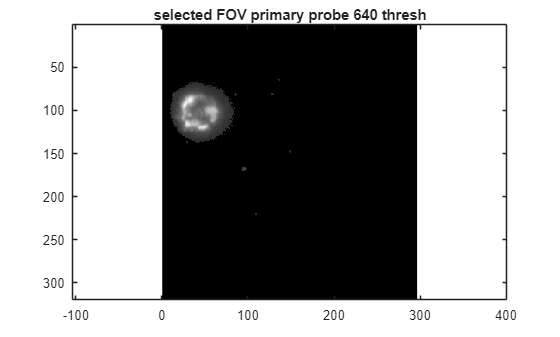


%% Threshold P-granules
I(I<Thresh640) = 0;
figure
Im640thresh = max(I,[],3);
imagesc(Im640thresh)
colormap gray
axis equal
title('selected FOV primary probe 640 thresh')

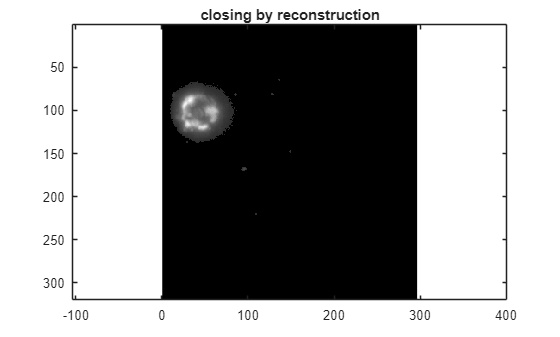


%% Morphological closing / opening
se = strel('sphere', dilateThresh);
Id = imdilate(I, se);
Icbr = imreconstruct(imcomplement(Id), imcomplement(I));
Icbr = imcomplement(Icbr);
figure
imagesc(max(Icbr,[],3))
colormap gray
axis equal
title('closing by reconstruction');

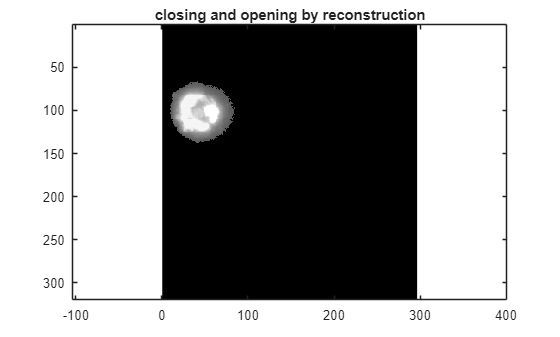


se = strel('sphere', erodeThresh);
Icbre = imerode(Icbr, se);
Icbrobr = imreconstruct(Icbre, Icbr);
figure
imagesc(max(Icbrobr,[],3))
colormap gray
axis equal
title('closing and opening by reconstruction');

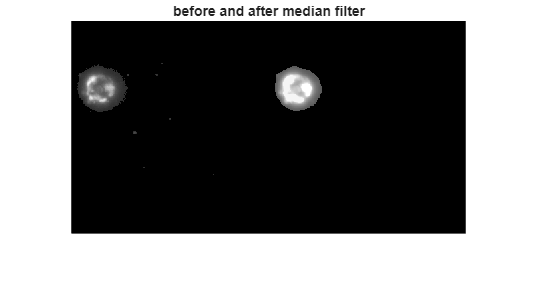


%% Median filter
J = medfilt3(Icbrobr, [5 5 5]);
figure
imshowpair(max(Icbr,[],3),max(J,[],3),'montage')
title('before and after median filter')

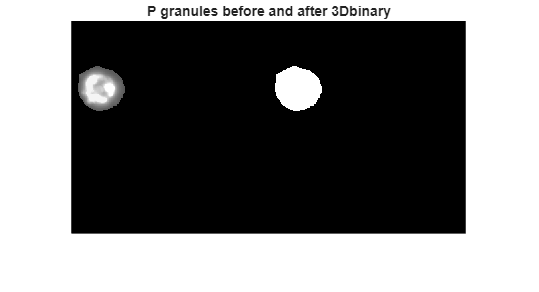

Icbrobr = J;

%% 3D binary mask of P granules
BW = imbinarize(Icbrobr, TerrbinaryThresh);
BW = imfill(BW, 'holes');
BW = imclose(BW, se);
figure
imshowpair(max(Icbrobr,[],3),max(BW,[],3),'montage')
title('P granules before and after 3Dbinary')

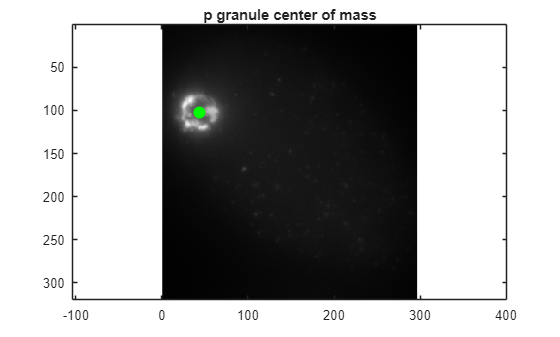


%% --- CORRECT P-GRANULE CENTROID ---
CC = bwconncomp(BW);
pstats = regionprops3(BW, 'all');
pcenter = pstats.Centroid; %Center of mass of the region, returned as a 1-by-3 vector of the form [centroid_x centroid_y and centroid_z]. 
if CC.NumObjects > 1
    pcenter = mean(pcenter);
end

%find closest nuccenter to pcenter and call this the pcell nucleus
figure
imagesc(Im640)
colormap gray
hold on
scatter3(pcenter(1), pcenter(2), pcenter(3), 80, 'filled','g')
title('p granule center of mass')
axis equal

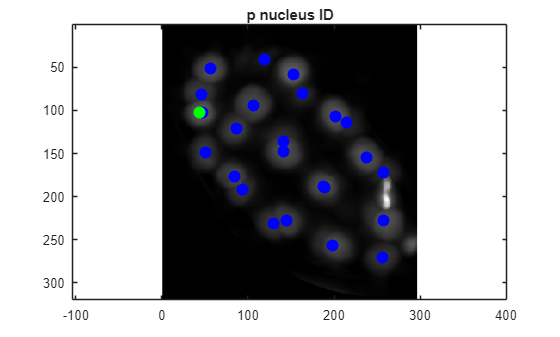


%compute Euclidean distances:
dist2 = sum((ncenters - pcenter) .^ 2, 2);
%find the smallest distance and use that as an index into ncenters:
pcellncenter = ncenters(dist2 == min(dist2),:);

% %% PLOT: nuclei + selected P nucleus

figure
%set(gcf,'Visible','on')
imagesc(ImDAPI)
colormap gray
hold on
scatter3(ncenters(:,1),ncenters(:,2),ncenters(:,3), 80, 'filled', 'b')
scatter3(pcenter(:,1),pcenter(:,2),pcenter(:,3), 80, 'filled', 'g')
plot3([pcenter(1,1) pcellncenter(1,1)],[pcenter(1,2) pcellncenter(1,2)],[pcenter(1,3) pcellncenter(1,3)], 'LineWidth', 3)
title('p nucleus ID')
axis equal

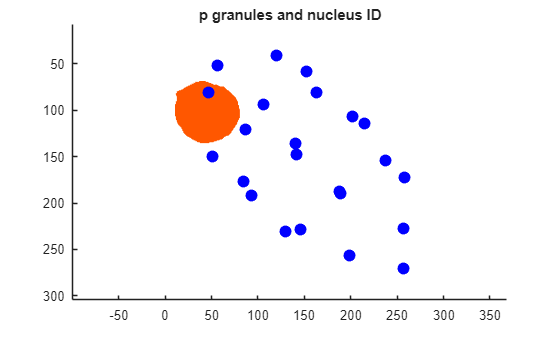


figure
%set(gcf,'Visible','on')
hold on
isosurface(BW)
colormap hot
scatter3(ncenters(:,1),ncenters(:,2),ncenters(:,3), 80, 'filled', 'b')
scatter3(pcellncenter(:,1),pcellncenter(:,2),pcellncenter(:,3), 80, 'filled', 'g')
set(gca,'YDir','reverse')
title('p granules and nucleus ID')
axis equal

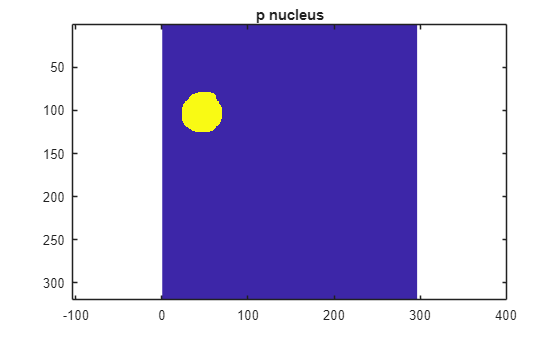


%find which nucL volume label pcellncenter is in and label it 1, somatic =0
clear nucnums
nucnums = zeros(length(ncenters),1);
for i = 1:length(ncenters)
    if pcellncenter == ncenters(i,:)
        nucnums(i,1) = 1;
    else
        nucnums(i,1) = 0;
    end
end

%pcellnucID = find(nucnums ==1);
pcellIndex = find(nucnums == 1);           % index into ncenters / nstats
cx = round(ncenters(pcellIndex,1));
cy = round(ncenters(pcellIndex,2));
cz = round(ncenters(pcellIndex,3));
pcellnucID = nucL(cy, cx, cz); 
somcellnucID = find(nucnums ==0);

% here split nucL into pcell or non-pcell 

pnucL = zeros(size(nucL));
pnucL(find(nucL == pcellnucID)) = 1; %copy pcellnucleus
pnucLmax = max(pnucL,[],3);
figure
%set(gcf,'Visible','on')
imagesc(pnucLmax)
axis equal
title('p nucleus')

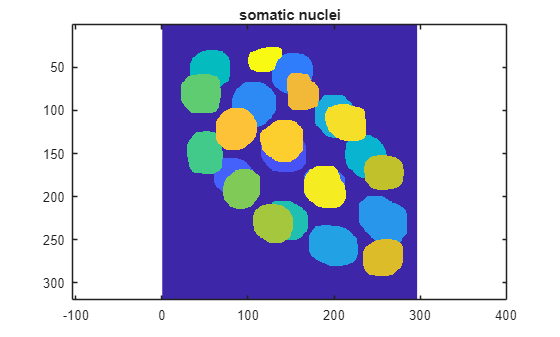



somnucL = nucL;
somnucL(find(nucL == pcellnucID)) = 0; %remove the pcellnucleus
somnucLmax = max(somnucL,[],3);
figure
%set(gcf,'Visible','on')
imagesc(somnucLmax)
axis equal
title('somatic nuclei')


save_tiffs = 1;
mkdir('tiffs')

% save and export as multipage tiff
if save_tiffs == 1
    % save(['Vol_Sample' SampleNum '_FOV' num2str(FOV) '_640.mat'],'pL');
    % outputFileName = ['tiffs/Vol_Sample' SampleNum '_FOV' num2str(FOV) '_640.tif'];
    % amin = 0;
    % amax = 100;
    % for K= 1:length(pL(1, 1, :))
    %     imwrite(mat2gray(pL(:,:,K), [amin amax]), outputFileName, 'WriteMode', 'append',  'Compression','none');
    % end
    
    I = ImageStack640(ceil(y1):ceil(y3),ceil(x1):ceil(x2),:);
    %save(['Raw_Sample' sampleNum '_FOV' num2str(FOV) '_640.mat'],'I');
    save(['Raw_Sample' num2str(sampleNum) '_FOV' num2str(FOV) '_640.mat'],'I');
    outputFileName = sprintf('tiffs/Raw_Sample%d_FOV%d_640.tif', sampleNum, FOV)
    amin = 100;
    amax = 1000;
    for K= 1:length(I(1, 1, :))
        imwrite(mat2gray(I(:,:,K), [amin amax]), outputFileName, 'WriteMode', 'append',  'Compression','none');
    end
end

outputFileName = 'tiffs/Raw_Sample6_FOV2_640.tif'


disp(zsz)

   101



## save nuclei coords and projection image

% save max projection image 
figure
%set(gcf,'Visible','on')
imagesc(ImDAPI)
colormap gray
hold on
scatter3(ncenters(:,1),ncenters(:,2),ncenters(:,3), 80, 'filled', 'b')
scatter3(pcellncenter(:,1),pcellncenter(:,2),pcellncenter(:,3), 80, 'filled', 'g')
text(ncenters(:,1),ncenters(:,2)+5,ncenters(:,3), num2str(nucID(:)), 'Color','k')
himage = imshow(nucLrgb);
himage.AlphaData = 0.3;
title(['Sample' num2str(sampleNum) 'FOV' num2str(FOV) ' age=' num2str(age)])
axis equal

pcellnucID

pcellnucID = uint16
3


mkdir('raw_images_1')

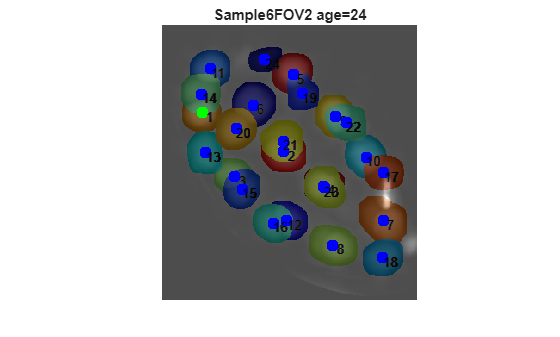

ncoords saved



save_age = 1;
if save_age ==1
    saveas(gcf, ['raw_images_1/Sample' num2str(sampleNum) 'FOV' num2str(FOV) '.tif'])
    save(['raw_images_1/Sample' num2str(sampleNum) 'FOV' num2str(FOV) 'ImDAPI.mat'], 'ImDAPI')

    % save data all together
    save(['Ncoords_1/Sample' num2str(sampleNum) 'FOV' num2str(FOV) '.mat'], 'nucL', 'nstats', 'pcellnucID', 'somcellnucID', 'pcellncenter')

    % save variables separately
    save(['Ncoords_1/parsed/Sample' num2str(sampleNum) 'FOV' num2str(FOV) 'nucL.mat'],'nucL')
    save(['Ncoords_1/parsed/Sample' num2str(sampleNum) 'FOV' num2str(FOV) 'nstats.mat'],'nstats')
    save(['Ncoords_1/parsed/Sample' num2str(sampleNum) 'FOV' num2str(FOV) 'pcellnucID.mat'],'pcellnucID')
    save(['Ncoords_1/parsed/Sample' num2str(sampleNum) 'FOV' num2str(FOV) 'somcellnucID.mat'],'somcellnucID')
    save(['Ncoords_1/parsed/Sample' num2str(sampleNum) 'FOV' num2str(FOV) 'pcellncenter.mat'],'pcellncenter')
    disp('ncoords saved')
end


%savefigspdf